# Cogs 118b final project: k-means using mnist data

George Liu

clear
load('data.mat')
load('label.mat')

## Using K-NN to cluster predetermined means:

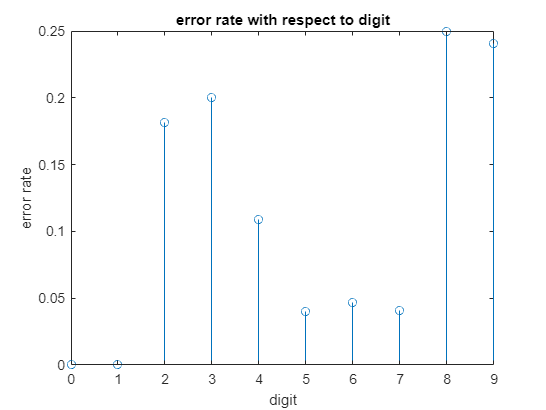

distance = 0;
distanceIteration = 0;
NNarray = zeros(length(imageTest),1);
NNindexarray = zeros(length(imageTest),1);
% part i, which is first determining the nearest neighbor and then
% providing a classification
% in addition, compute the error rate for each individual class
for x = 1:length(imageTest)
 for i = 1:length(imageTrain)
 % for both imageTest and imageTrain, we have to first convert them
 % into 784x1 arrays holding all the pixels

 imgtest784 = reshape(imageTest(:,:,x),[],1);
 imgtrain784 = reshape(imageTrain(:,:,i),[],1);
 % find the euclidean distance and test it on the test database
 for j = 1:length(imgtrain784)
 distanceIteration = distanceIteration + abs(imgtrain784(j) - imgtest784(j));
 end
 distanceIteration = sqrt(distanceIteration);
 % for each point, test if the distance is closer or not; if it is
 % replace with the new distance to categorize as the "nearest"
 % after catergorizing as nearest, then go to training label's index
 % to find the correct label and assign it
 if (i == 1)
 distance = distanceIteration;
 NNarray(x) = labelTrain(i);
 NNindexarray(x) = i;
 elseif (distanceIteration < distance)
 distance = distanceIteration;
 NNarray(x) = labelTrain(i);
 NNindexarray(x) = i;
 end
 end
end
% find number of appearances of each digit
digitcounter = zeros(10,1);
for i = 1:length(labelTest)
 currentdigit = labelTest(i);
 digitcounter(currentdigit + 1) = digitcounter(currentdigit + 1) + 1;
end
% Calculate the number of each class the NN classifier got wrong by
% comparing the stored data that we predict itht the labeled data
incorrectCount = zeros(10,1);
for i = 1:length(labelTest)
 currentdigit = labelTest(i);
 if(labelTest(i) ~= NNarray(i))
 incorrectCount(currentdigit + 1) = incorrectCount(currentdigit + 1) + 1;
 end
end

errorRate = zeros(10,1);
for i = 1:10
 errorRate(i) = (incorrectCount(i) / digitcounter(i));
end

xaxis = [0;1;2;3;4;5;6;7;8;9];
figure()
stem(xaxis,errorRate)
title("error rate with respect to digit")
ylabel("error rate")
xlabel("digit")

## Using K-means algorithm to cluster randomly assigned means

clear
load('data.mat')
load('label.mat')

class_means = zeros(28,28,10);
% For K-means algorithm, we need to first initialize "K" means,
% we will choose K=10 b/c there are 10 total digits
random_ind = sort(randi([1 5000],10,1))

random_ind =          380
         617
         920
        1200
        1200
        1755
        2010
        2567
        3111
        4266


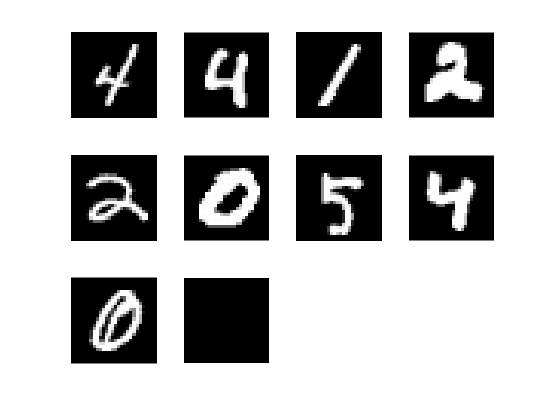

current_ind = 1;
% if the current iteration is part of the indicies we generated, add it to
% our class means
for i = 1:5000
    if(ismember(i,random_ind))
        class_means(:,:,current_ind) = imageTrain(:,:,i);
        current_ind = current_ind + 1;
    end
end

figure()
% as we can see, the randomly intiailized k-means are very inaccurate
for i = 1:10
    subplot(3,4,i)
    imshow(class_means(:,:,i),[])
end

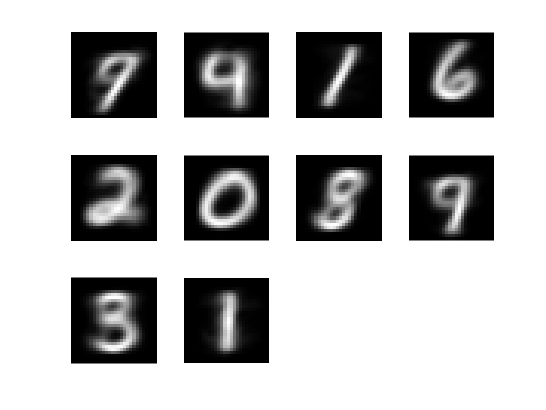

changes = 11;
benchmark = 0;
closest_neighbor = zeros(length(imageTrain),1);
iterations = 0;
% recompute k-means using Euclidean Distance metric
while(changes > 10)
    changes = 0;
    for i = 1:5000
        previous = closest_neighbor(i);
        reshaped_images = reshape(imageTrain(:,:,i),[],1);
        for j = 1:10
            curr_dist_tot = 0;
            reshaped_means = reshape(class_means(:,:,j),[],1);
            for k = 1:784
                curr_dist_tot = curr_dist_tot + abs(reshaped_images(k) - reshaped_means(k))^2;
            end
            curr_dist_tot = sqrt(curr_dist_tot);
            if (j == 1)
                benchmark = curr_dist_tot;
                closest_neighbor(i) = j-1;
            elseif (curr_dist_tot < benchmark)
                benchmark = curr_dist_tot;
                closest_neighbor(i) = j-1;
            end
        end
        if(closest_neighbor(i) ~= previous)
            changes = changes + 1;
        end
        benchmark = 0;
    end
    for i = 1:10
        count = 0;
        img_mean = zeros(28,28);
        for j = 1:5000
            if(closest_neighbor(j) == i-1)
                count = count + 1;
                img_mean = img_mean + imageTrain(:,:,j);
            end
        end
        class_means(:,:,i) = img_mean/count;
    end
    iterations = iterations + 1;
end
figure()
% show the new k=means after recomputing 
for i = 1:10
    subplot(3,4,i)
    imshow(class_means(:,:,i),[])
end

## Using K-means, but with different intializations from the original 

% repeating part 2, but with different intialization of random 10 means
random_ind = sort(randi([1 5000],10,1))

random_ind =          249
         557
        1689
        1847
        2087
        2447
        2455
        4501
        4514
        4724


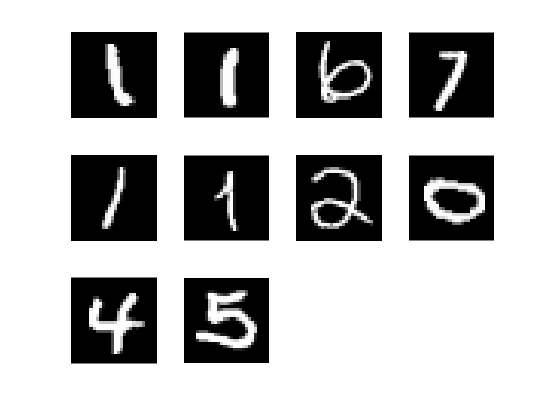

current_ind = 1;
for i = 1:5000
    if(ismember(i,random_ind))
        class_means(:,:,current_ind) = imageTrain(:,:,i);
        current_ind = current_ind + 1;
    end
end
figure()
for i = 1:10
    subplot(3,4,i)
    imshow(class_means(:,:,i),[])
end

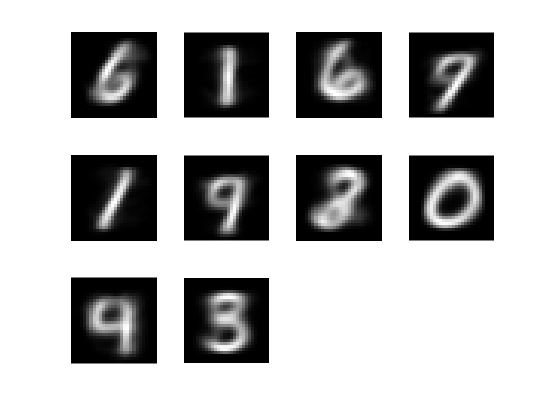

changes = 11;
benchmark = 0;
closest_neighbor = zeros(length(imageTrain),1);
iterations = 0;
while(changes > 10)
    changes = 0;
    for i = 1:5000
        previous = closest_neighbor(i);
        reshaped_images = reshape(imageTrain(:,:,i),[],1);
        for j = 1:10
            curr_dist_tot = 0;
            reshaped_means = reshape(class_means(:,:,j),[],1);
            for k = 1:784
                curr_dist_tot = curr_dist_tot + abs(reshaped_images(k) - reshaped_means(k))^2;
            end
            curr_dist_tot = sqrt(curr_dist_tot);
            if (j == 1)
                benchmark = curr_dist_tot;
                closest_neighbor(i) = j-1;
            elseif (curr_dist_tot < benchmark)
                benchmark = curr_dist_tot;
                closest_neighbor(i) = j-1;
            end
        end
        if(closest_neighbor(i) ~= previous)
            changes = changes + 1;
        end
        benchmark = 0;
    end
    for i = 1:10
        count = 0;
        img_mean = zeros(28,28);
        for j = 1:5000
            if(closest_neighbor(j) == i-1)
                count = count + 1;
                img_mean = img_mean + imageTrain(:,:,j);
            end
        end
        class_means(:,:,i) = img_mean/count;
    end
    iterations = iterations + 1;
end
figure()
for i = 1:10
    subplot(3,4,i)
    imshow(class_means(:,:,i),[])
end